%% 
CL    = 0.95;
beta  = 1e-6:1e-6:1e-3;
%Nruns = -log(1-0.95)/beta(1); % theoretical num of runs to be run
Nruns = 300; % actual num of runs used due to processing time

results = zeros(length(beta),2);
for idx_beta = 1:length(beta)
    Pd = 0;
    Pfa = 0;
    for n = 1:Nruns
        [Pd_tmp, Pfa_tmp] = sca(beta(idx_beta));   
        Pfa = Pfa + Pfa_tmp;  
        Pd  = Pd + Pd_tmp;
    end
    results(idx_beta,1) = Pfa/Nruns;    
    results(idx_beta,2) = Pd/Nruns;
end

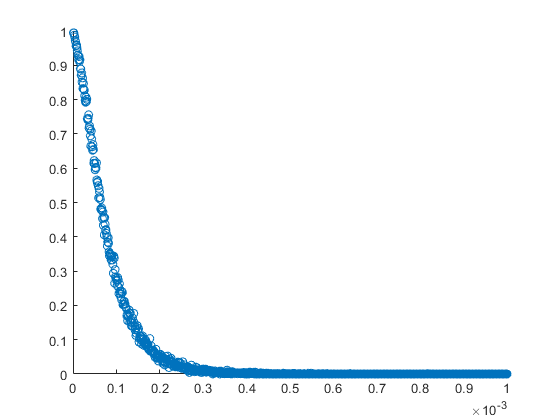

% "classifier"
% "predictions"

% raw roc
scatter(beta,results(:,1))

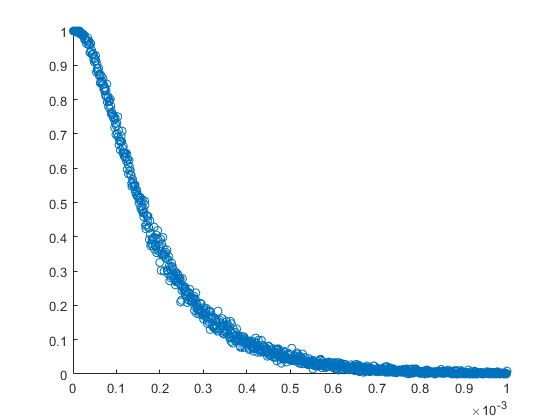

scatter(beta,results(:,2))

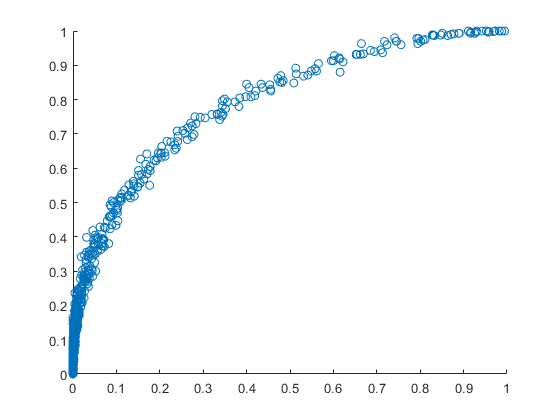

scatter(results(:,1),results(:,2))


% average roc
[C,ia,idx] = unique(results(:,1),'stable');
val = accumarray(idx,results(:,2),[],@mean); 
averages_vals = [C val];
scatter(averages_vals(:,1),averages_vals(:,2),'k')
hold on

% optimal roc point
[roc, roc_idx] = max(averages_vals(:,2)-averages_vals(:,1));
optimal_beta = beta(roc_idx);
scatter(averages_vals(roc_idx,1),averages_vals(roc_idx,2),'r','filled')
hold off

disp(["optimal P_{d}   =" roc])

    "optimal P_{d}   ="    "0.47167"



disp(["optimal P_{fa}  =" averages_vals(roc_idx,2)])

    "optimal P_{fa}  ="    "0.64167"



disp(["optimal \beta   =" beta(roc_idx)])

    "optimal \beta   ="    "0.000123"



disp(["classifier perf =" trapz(averages_vals(:,1),averages_vals(:,2))])

    "classifier perf ="    "-0.79131"



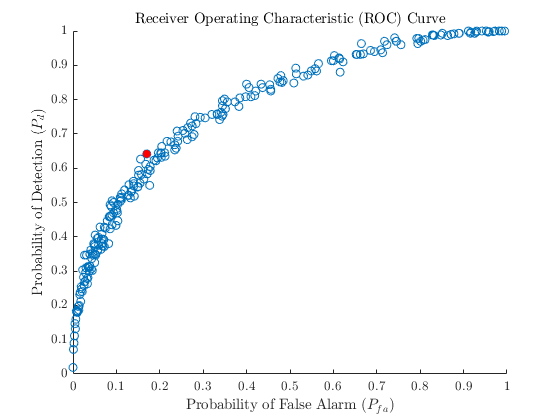



title('Receiver Operating Characteristic (ROC) Curve','interpreter','latex')
xlabel('Probability of False Alarm $(P_{fa})$','interpreter','latex')
ylabel('Probability of Detection $(P_{d})$','interpreter','latex')
set(gca,'TickLabelInterpreter','latex')


print('../images/roc', '-dpng')